# Part 1

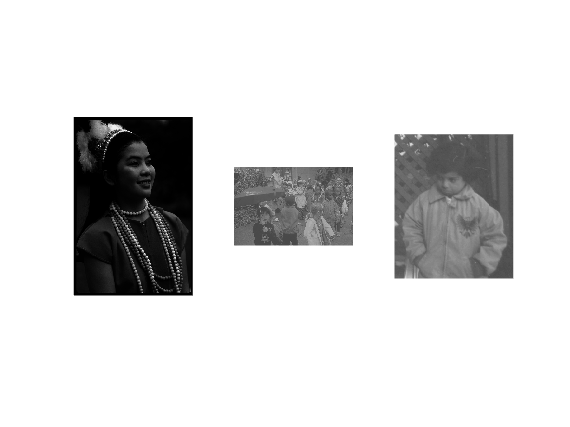

%% 1.1
% read the images
dark = imread("dark.tif");
narrow = imread("narrow.tif");
pout = imread("pout.tif");

figure;
subplot(131)
imshow(dark);

subplot(132);
imshow(narrow);

subplot(133);
imshow(pout);

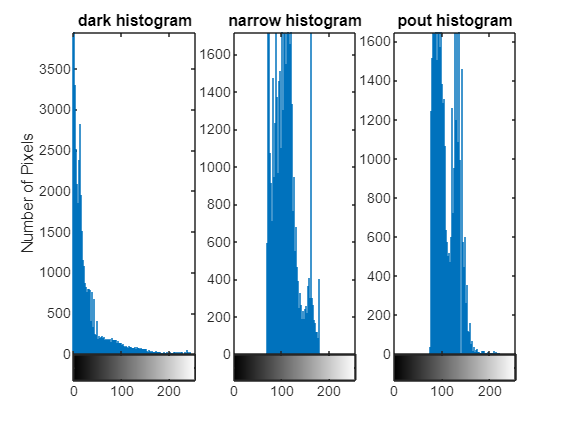


% plot original histograms in one figure with x, y labels and titles
figure;
subplot(131)
imhist(dark)
title("dark histogram")
ylabel("Number of Pixels")

subplot(132)
imhist(narrow)
title("narrow histogram")
xlabel("Grayscale Range")

subplot(133)
imhist(pout)
title("pout histogram")

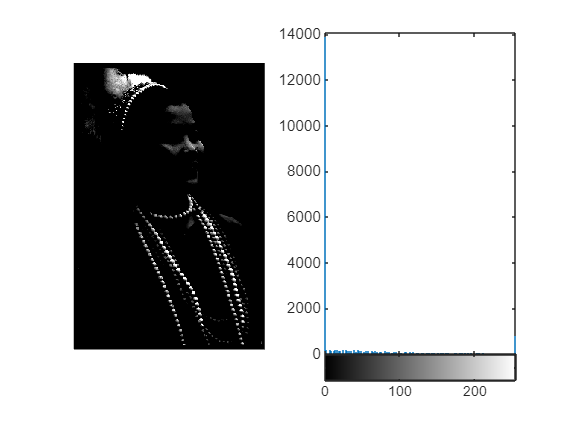


%% Part 1.2
T1 = 70;
T2 = 180;
a = T1/255;
b = T2/255;

D = imadjust(dark, [a b],[0 1]);
N = imadjust(narrow, [a b], [0 1]);
P = imadjust(pout, [a b], [0 1]);

% plot new dark img and hist
figure;
subplot(121)
imshow(D)
subplot(122)
imhist(D)

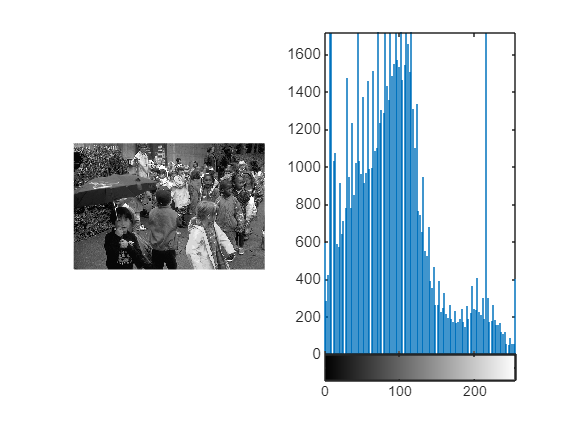


% plot new narrow img and hist
figure;
subplot(121)
imshow(N)
subplot(122)
imhist(N)

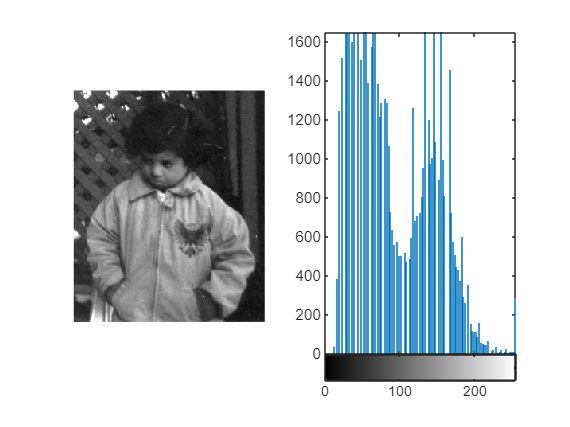


% plot new pout img and hist
figure;
subplot(121)
imshow(P)
subplot(122)
imhist(P)

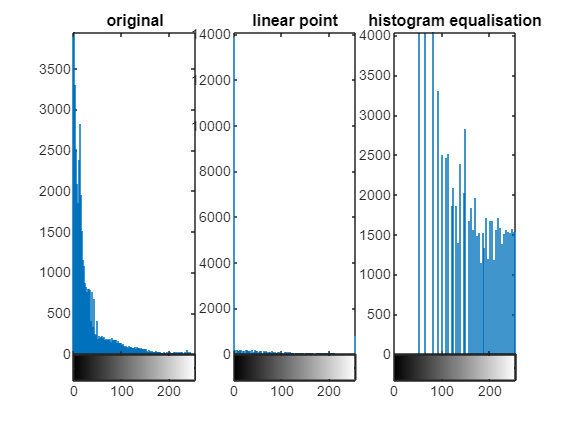


%$ Part 1.3

% histogram equalization
D1 = histeq(dark);
N1 = histeq(narrow);
P1 = histeq(pout);

% plot to compare 2 dark histogram equa methods
figure;
subplot(131);
imhist(dark);
title("original")
subplot(132);
imhist(D);
title("linear point")
subplot(133);
imhist(D1);
title("histogram equalisation")

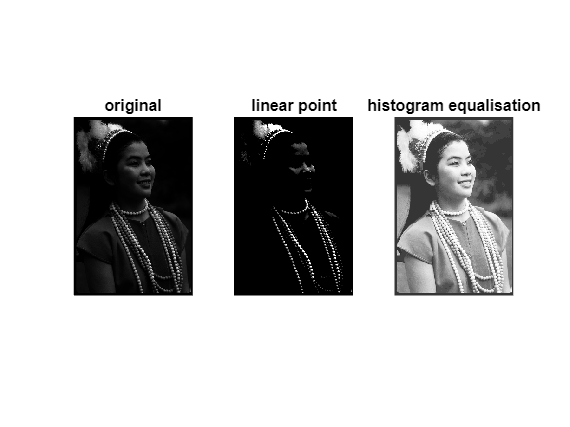


figure;
subplot(131);
imshow(dark);
title("original")
subplot(132);
imshow(D);
title("linear point")
subplot(133);
imshow(D1);
title("histogram equalisation")

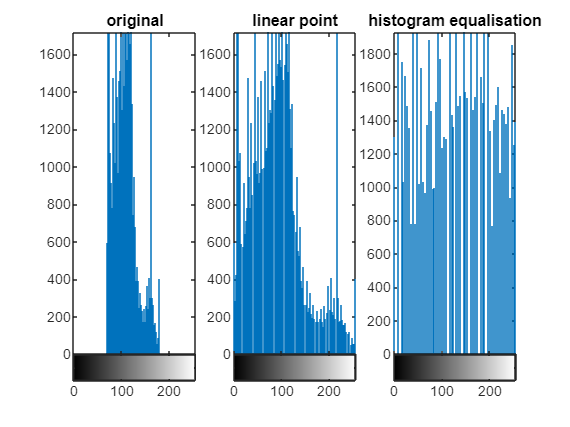


% compare narrow histograms
figure;
subplot(131);
imhist(narrow);
title("original")
subplot(132);
imhist(N);
title("linear point")
subplot(133);
imhist(N1);
title("histogram equalisation")

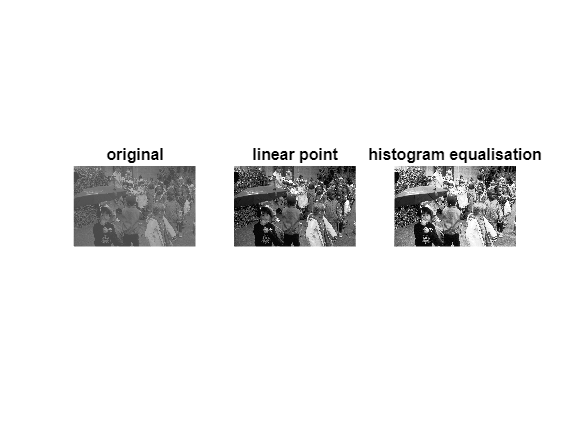


figure;
subplot(131);
imshow(narrow);
title("original")
subplot(132);
imshow(N);
title("linear point")
subplot(133);
imshow(N1);
title("histogram equalisation")

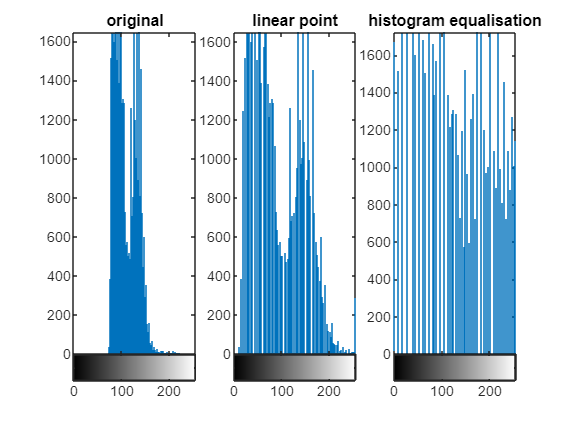


% compare pout histograms
figure;
subplot(131);
imhist(pout);
title("original")
subplot(132);
imhist(P);
title("linear point")
subplot(133);
imhist(P1);
title("histogram equalisation")

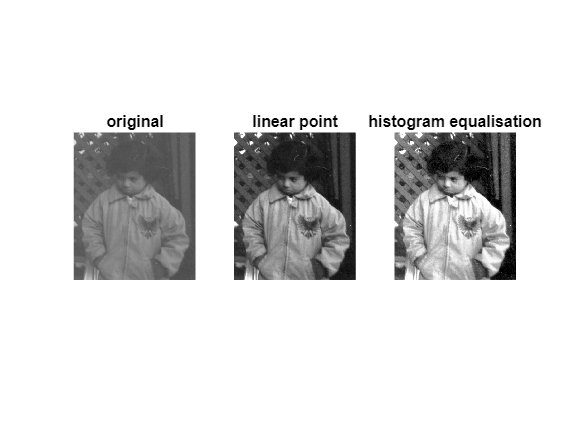


figure;
subplot(131);
imshow(pout);
title("original")
subplot(132);
imshow(P);
title("linear point")
subplot(133);
imshow(P1);
title("histogram equalisation")

## Part 2

% generate negative of dark.tiff
figure;
dark = imread("dark.tif");
dark_negative = imadjust(dark, [0 1], [1 0])

dark_negative = 384×256 uint8 matrix
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255

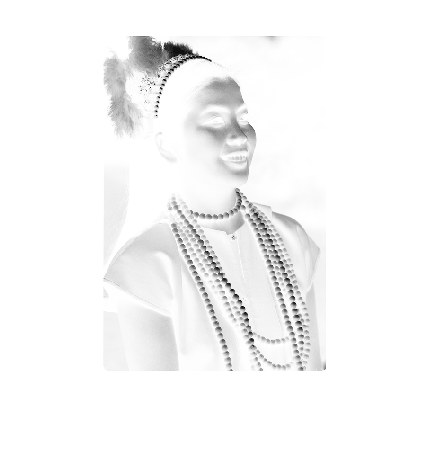


imshow(dark_negative)

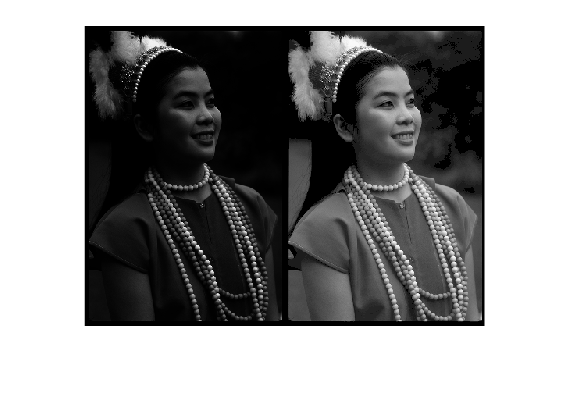

% different gamma values to the dark.tif image
figure;
dark = imread("dark.tif");
dark_gamma = imadjust(dark, [], [], 0.4);

imshowpair(dark, dark_gamma, "montage")

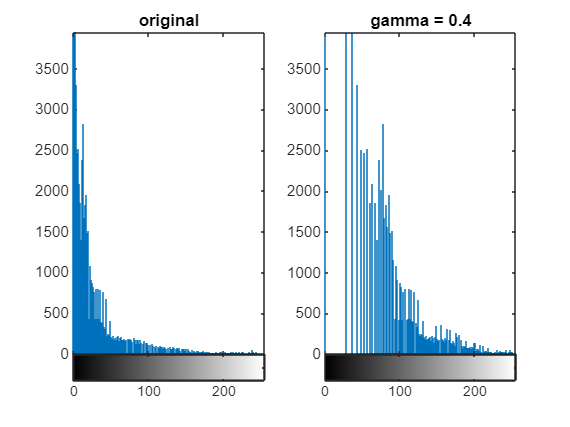


figure;
subplot(121)
imhist(dark)
title("original")

subplot(122)
imhist(dark_gamma)
title("gamma = 0.4")

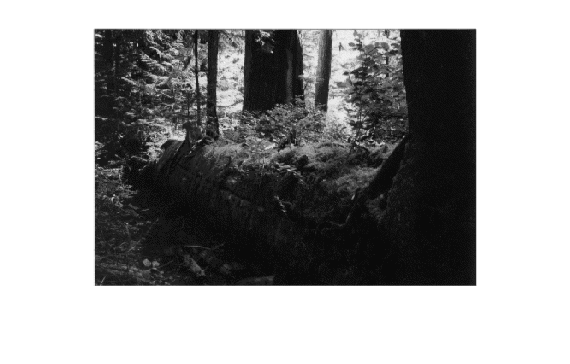

% forest image conversion from index to grayscale
figure;
[X, map] = imread("forest.tif");

forest_gs = ind2gray(X, map);
imshow(forest_gs)

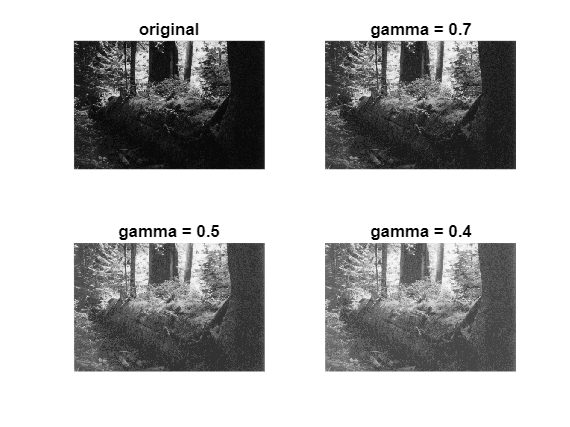


% adjust gamma values for grayscale forest image
figure;
forest_gamma_7 = imadjust(forest_gs, [], [], 0.7);
forest_gamma_5 = imadjust(forest_gs, [], [], 0.5);
forest_gamma_4 = imadjust(forest_gs, [], [], 0.4);

% plot in 1 fig
subplot(221);
imshow(forest_gs);
title("original");

subplot(222);
imshow(forest_gamma_7);
title("gamma = 0.7");

subplot(223);
imshow(forest_gamma_5);
title("gamma = 0.5");

subplot(224);
imshow(forest_gamma_4);
title("gamma = 0.4");